clear
t = [0:0.2:20];
v = -0.2*(t-10).^(2) + 20

v =          0    0.7920    1.5680    2.3280    3.0720    3.8000    4.5120    5.2080    5.8880    6.5520    7.2000    7.8320    8.4480    9.0480    9.6320   10.2000   10.7520   11.2880   11.8080   12.3120   12.8000   13.2720   13.7280   14.1680   14.5920   15.0000   15.3920   15.7680   16.1280   16.4720   16.8000   17.1120   17.4080   17.6880   17.9520   18.2000   18.4320   18.6480   18.8480   19.0320   19.2000   19.3520   19.4880   19.6080   19.7120   19.8000   19.8720   19.9280   19.9680   19.9920


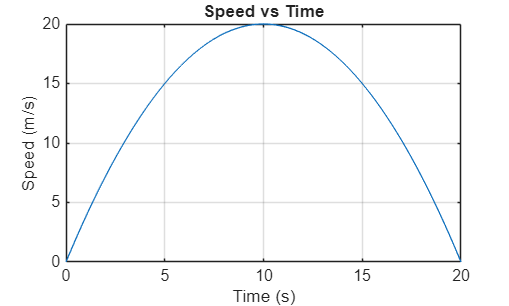


plot(t, v);
xlabel('Time (s)');
ylabel('Speed (m/s)');
title('Speed vs Time');
grid on;


a = diff(v)

a =     0.7920    0.7760    0.7600    0.7440    0.7280    0.7120    0.6960    0.6800    0.6640    0.6480    0.6320    0.6160    0.6000    0.5840    0.5680    0.5520    0.5360    0.5200    0.5040    0.4880    0.4720    0.4560    0.4400    0.4240    0.4080    0.3920    0.3760    0.3600    0.3440    0.3280    0.3120    0.2960    0.2800    0.2640    0.2480    0.2320    0.2160    0.2000    0.1840    0.1680    0.1520    0.1360    0.1200    0.1040    0.0880    0.0720    0.0560    0.0400    0.0240    0.0080


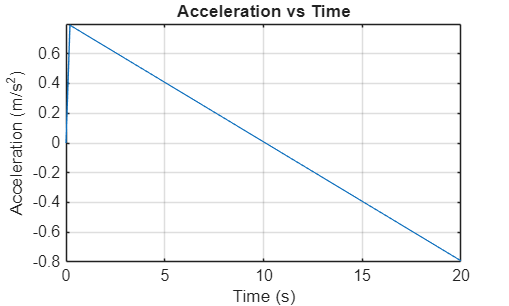

a = [0, a]; % Prepend a zero to match the length of v for plotting
plot(t, a);
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
title('Acceleration vs Time');
grid on;


% We can see that the speed is at its highest point after 10 seconds
% have passed. Furthermore, if we look at the Acceleration graph, we
% can see that when time is 10, the acceleration is 0.008, just barely 
% above zero. 

% - In the context of speed, the vertex refers to the point at which the
% driver takes their foot off the gas and puts it on the brake. The
% speed is gradually increasing, then gradually decreases. 

% - We can see that the acceleration constantly decreases after 
% increasing to about 0.8m/s^2 instantaneously. This represents the car
% starting at a standstill, then immediately accelerating, then slowly
% accelerating slower. The car is still accelerating and gaining speed,
% but just at a slower rate. After 10 seconds, the car's acceleration
% reaches zero, then constantly goes below zero. At this point, the car's
% acceleration is negative, and it starts losing speed. Remember, the
% car is still moving forward, it is just slowing down, and the rate at
% which it is losing speed is increasing. Eventually, the car comes to a
% stop and the acceleration should return to zero. 